# Preguntas:

a) ¿Cuál fue el o los parámetros que se modifican para obtener una trayectoria recta? ¿Por qué?

Para obtener una trayectoria recta, se deben ajustar los siguientes parámetros:

- Waypoints

- Lookahead Distance con un valor alto

b) ¿Cuál fue el o los parámetros que se modifican para obtener una trayectoria curva? ¿Por qué?

Para obtener una trayectoria curva, se deben ajustar los siguientes parámetros:

- Waypoints

- Lookahead Distance con un valor bajo

 c) ¿Cuál fue el o los parámetros que se modifican para obtener un giro? ¿Por qué?

Para obtener un giro, se deben ajustar los siguientes parámetros:

- Waypoints

- Max Angular Velocity el valor debe ser alto para permitir que el robot realice giros rápidos

d) ¿Qué papel desempeña el vector del tiempo en la generación de la trayectoria?

El vector del tiempo define los intervalos de tiempo en los que el robot actualizará su posición y su control.

Un tiempo de muestreo más pequeño da actualizaciones más frecuentes, por lo tanto, una trayectoria más suave y precisa.

La longitud del vector de tiempo define la duración total de la simulación.

e) ¿Cuáles fueron los parámetros que se ajustaron para obtener las dimensiones de las trayectorias deseadas?

Para obtener las dimensiones de las trayectorias deseadas, se ajustaron principalmente los siguientes parámetros:

- Waypoints: La posición de cada waypoint especifica las coordenadas x e y que el robot debe seguir.

- Lookahead Distance: Afecta cómo de suavemente el robot sigue los waypoints

- Desired Linear Velocity: La velocidad lineal deseada determina qué tan rápido se mueve el robot a lo largo de la trayectoria. 

- Max Angular Velocity: Asegura que el robot puede girar adecuadamente para seguir la trayectoria, especialmente en trayectorias con muchos giros o curvas.

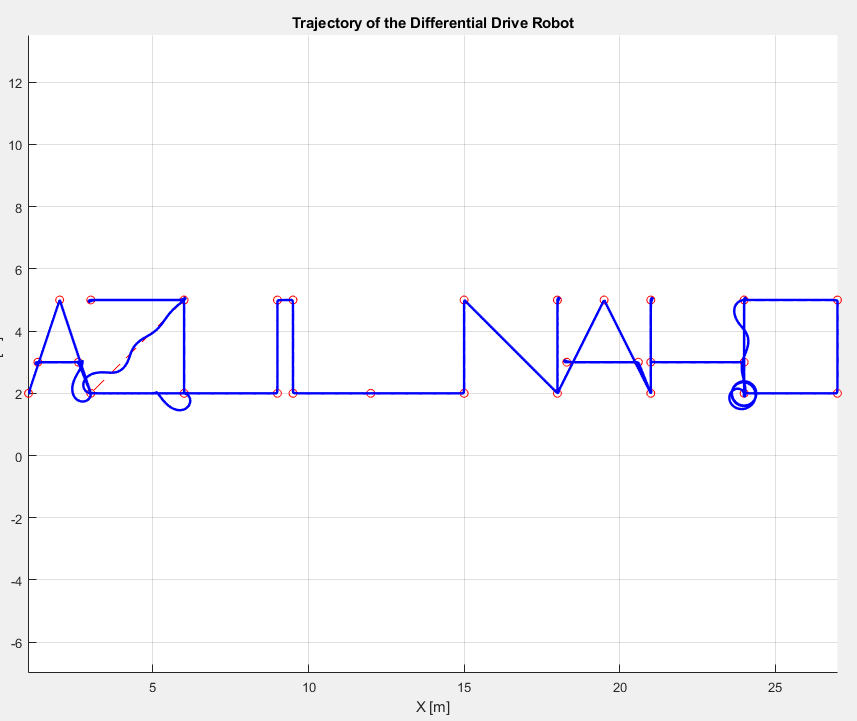

R = 0.2;                        % Wheel radius [m]
L = 0.2;                        % Wheelbase [m]
dd = DifferentialDrive(R,L);

% Sample time and time array
sampleTime = 0.1;               % Sample time [s] (reduced for faster updates)
tVec = 0:sampleTime:350;         % Time array

% Initial conditions
initPose = [1;2;0];             % Initial pose (x y theta)
pose = zeros(3,numel(tVec));    % Pose matrix
pose(:,1) = initPose;

% Create lidar sensor
lidar = LidarSensor;
lidar.sensorOffset = [0,0];
lidar.scanAngles = linspace(-pi/2,pi/2,200);
lidar.maxRange = 0.5;

## Path planning and following

Create waypoints

waypoints = [initPose(1:2)'; 
             1 2;
             2 5;
             3 2;
             2.6 3;
             1.3 3;
             2.6 3;
             3 2;
             6 2;
             3 2;
             6 5;
             3 5;
             6 5;
             6 2;
             9 2;
             9 5;
             9.5 5;
             9.5 2;
             12 2;
             15 2;
             15 5;
             18 2;
             18 5;
             18 2;
             19.5 5;
             21 2;
             20.6 3;
             18.3 3;
             20.6 3;
             21 2;
             21 5;
             21 3;
             24 3;
             24 5;
             24 2;
             27 2;
             27 5;
             24 5;
             24 2
             ];

% Pure Pursuit Controller
controller = controllerPurePursuit;
controller.Waypoints = waypoints;
controller.LookaheadDistance = 0.1;
controller.DesiredLinearVelocity = 0.3;  % Increased speed for faster updates
controller.MaxAngularVelocity = 30;      % Increased max angular velocity

% Vector Field Histogram (VFH) for obstacle avoidance
vfh = controllerVFH;
vfh.DistanceLimits = [0.05 3];
vfh.NumAngularSectors = 36;
vfh.HistogramThresholds = [5 10];
vfh.RobotRadius = L;
vfh.SafetyDistance = L;
vfh.MinTurningRadius = 0.25;

## Simulation loop

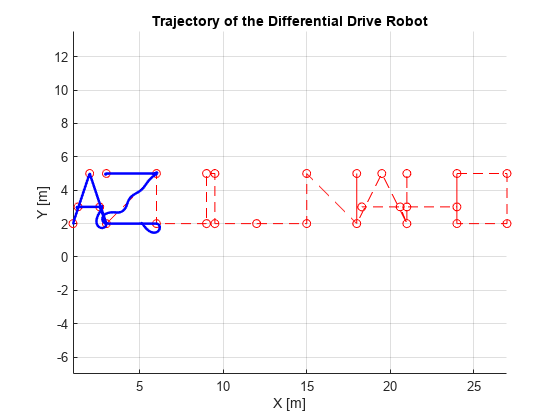

r = rateControl(1/sampleTime);

figure; hold on;
plot(waypoints(:,1), waypoints(:,2), 'ro--'); % Plot waypoints
title('Trajectory of the Differential Drive Robot');
xlabel('X [m]');
ylabel('Y [m]');
grid on;
axis equal;

for idx = 2:numel(tVec)
    % Get the sensor readings
    curPose = pose(:,idx-1);
    ranges = lidar(curPose);
    
    % Run the path following and obstacle avoidance algorithms
    [vRef,wRef,lookAheadPt] = controller(curPose);
    targetDir = atan2(lookAheadPt(2)-curPose(2),lookAheadPt(1)-curPose(1)) - curPose(3);
    steerDir = vfh(ranges, lidar.scanAngles, targetDir);
    if ~isnan(steerDir) && abs(steerDir-targetDir) > 0.1
        wRef = 0.5*steerDir;
    end
    
    % Control the robot
    velB = [vRef;0;wRef];             % Body velocities [vx;vy;w]
    vel = bodyToWorld(velB,curPose);  % Convert from body to world
    
    % Perform forward discrete integration step
    pose(:,idx) = curPose + vel*sampleTime;
    
    % Update visualization
    plot(pose(1,idx), pose(2,idx), 'b.');
    drawnow;
    
    waitfor(r);
end


% Plot final trajectory
plot(pose(1,:), pose(2,:), 'b');
legend('Waypoints', 'Trajectory');